CS 567 (HW1)

Sparsh Agarwal

9075905142

Q1.a.

new = normrnd(0,1,[4 4])

new =    -0.1623   -0.8757   -0.1922   -1.0642
   -0.1461   -0.4838   -0.2741    1.6035
   -0.5320   -0.7120    1.5301    1.2347
    1.6821   -1.1742   -0.2490   -0.2296


newcopy = new;

b.

new_mod = new( new>=0)

new_mod =     1.6821
    1.5301
    1.6035
    1.2347


c.

[i,j,v] = find(new>0) 

i =      4
     3
     2
     3


j =      1
     3
     4
     4


v = 4×1 logical array
   1
   1
   1
   1


d.

newcopy(newcopy > 0) = 1;
newcopy(newcopy < 0) = 0

newcopy =      0     0     0     0
     0     0     0     1
     0     0     1     1
     1     0     0     0


Q2.

newmod = new-new(1,1)

newmod =          0   -0.7134   -0.0299   -0.9019
    0.0163   -0.3215   -0.1117    1.7658
   -0.3697   -0.5497    1.6924    1.3970
    1.8444   -1.0119   -0.0867   -0.0673


Q3.a. The first two dimensions represent the number of pixels along the hight and width of the image, the third dimension represents the three color channels(RGB) that are used to define the image. Range of values in the image is 0 to 255.

img1 = imread('img_001.ppm');
whos img1

  Name        Size                 Bytes  Class    Attributes

  img1      605x700x3            1270500  uint8              



v = img1(:);
min(v)

ans = uint8
0

max(v)

ans = uint8
255

b.imshow is an image processing toolbox which treats the matrix as an image. It has numerous options and modifications that can be made to the image, like pixel intensities, axes control, aspect ratio and also provides more control over colormaps.

imagesc does not provide such freedom for customizations.

`image` considers matrix as just a array of numbers, which have no meaning with color with respect to the image. The colors used to represent each value might be meaningless to the representation of the matrix as an image.

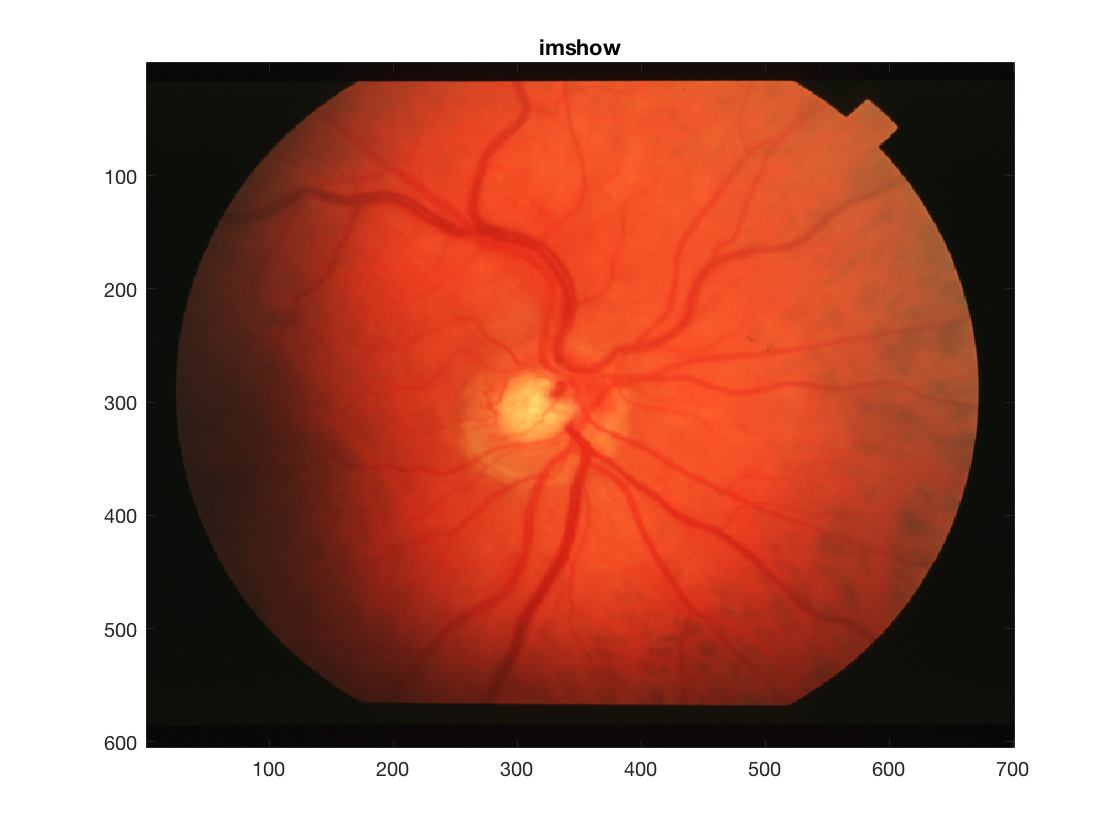

figure
image(img1)
title('imshow')

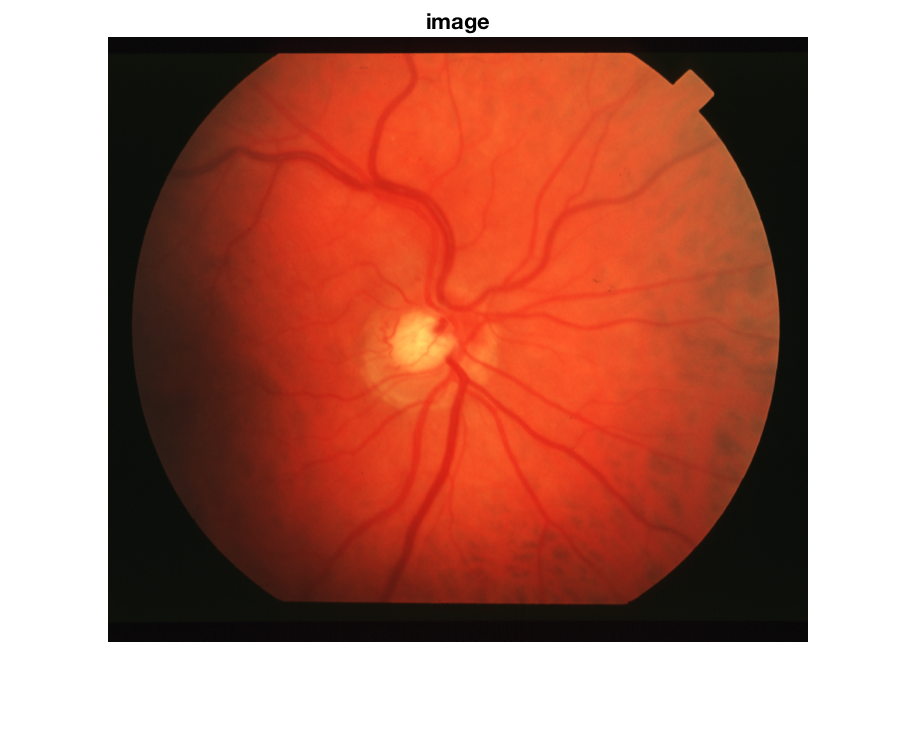


figure
imshow(img1)
title('image')

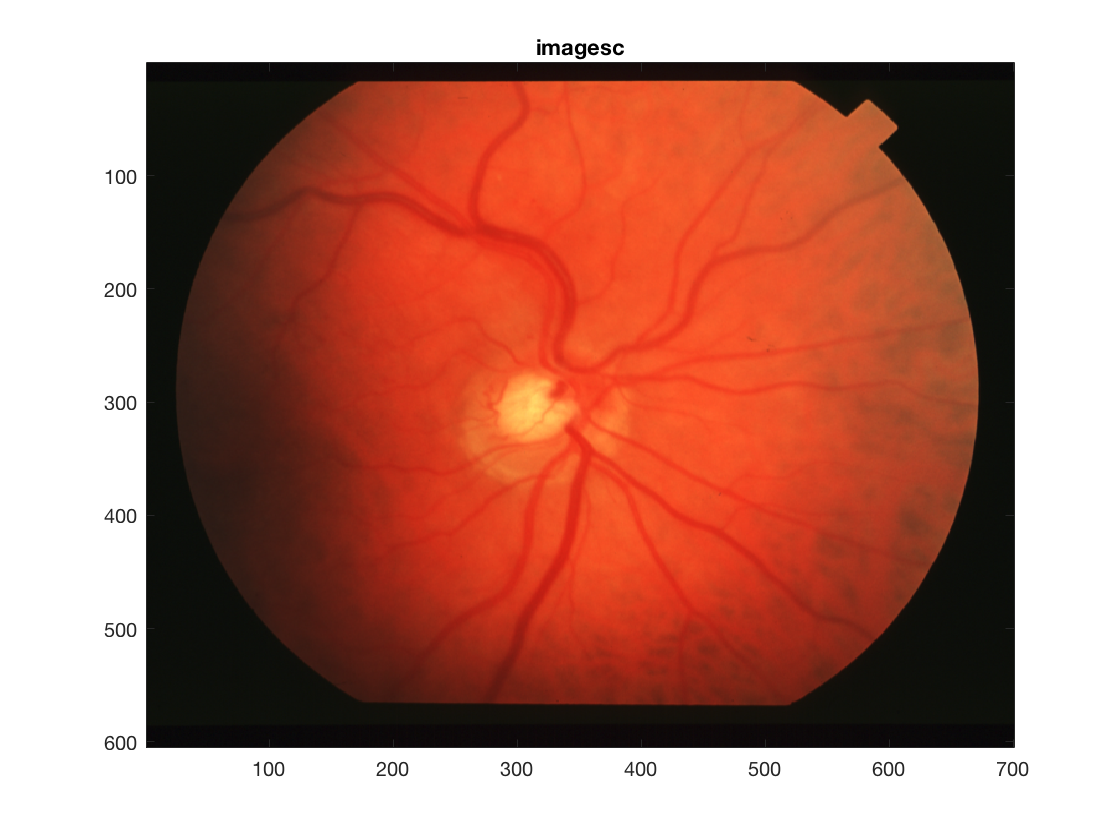


figure
imagesc(img1)
title('imagesc')

c. Imagesc in this part preserved the aspect ratio unlike in previous part.

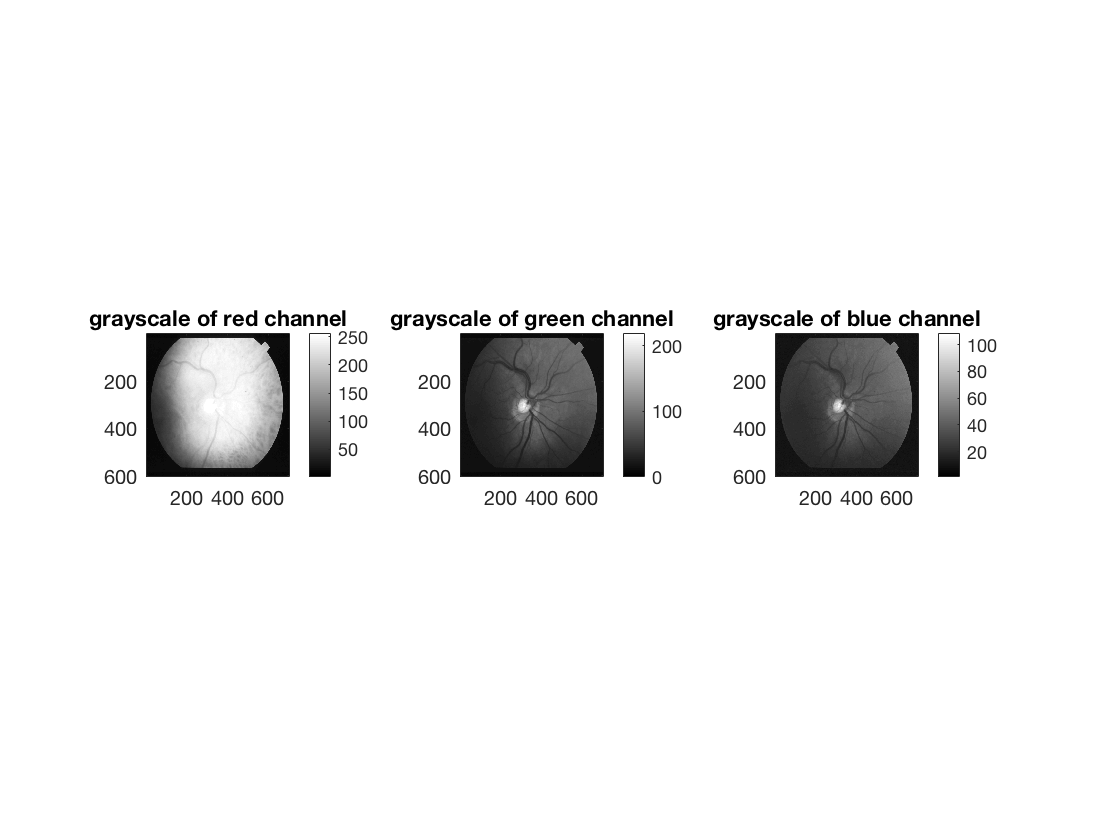

r_gray = double(img(:,:,1));
g_gray = double(img(:,:,2));
b_gray = double(img(:,:,3));

figure
colormap('gray')

subplot(1,3,1)
imagesc(r_gray)
axis('square')
colorbar
title('grayscale of red channel')

subplot(1,3,2)  
imagesc(g_gray)
axis('square')
colorbar
title('grayscale of green channel')

subplot(1,3,3)  
imagesc(b_gray)
axis('square')
colorbar
title('grayscale of blue channel')

Q4.

img = imread('img_001.ppm'); 
red = double(img(:,:,1)); % Red channel
% whos red
img_new = zeros(length(red(:,1)), length(red));
% whos img_new
for col = 2:length(red)-1
  for row = 2:length(red(:,1))-1
      img_new(row, col) = (red(row-1,col-1)+red(row,col-1)+red(row+1,col-1)+red(row-1,col)+red(row,col)+red(row+1,col)+red(row-1,col+1)+red(row,col+1)+red(row+1,col+1))/9;
  end
end

red(1:5,1:5)

ans =     11    10    11     9    12
    10     9    10    10    11
     9    10    11     9    12
    10    11    10     8     9
    10    11    10    10     9


img_new(1:5,1:5)

ans =          0         0         0         0         0
         0   10.1111    9.8889   10.5556   10.4444
         0   10.0000    9.7778   10.0000   10.0000
         0   10.2222   10.0000    9.7778    9.5556
         0   10.2222    9.7778    9.2222    9.2222


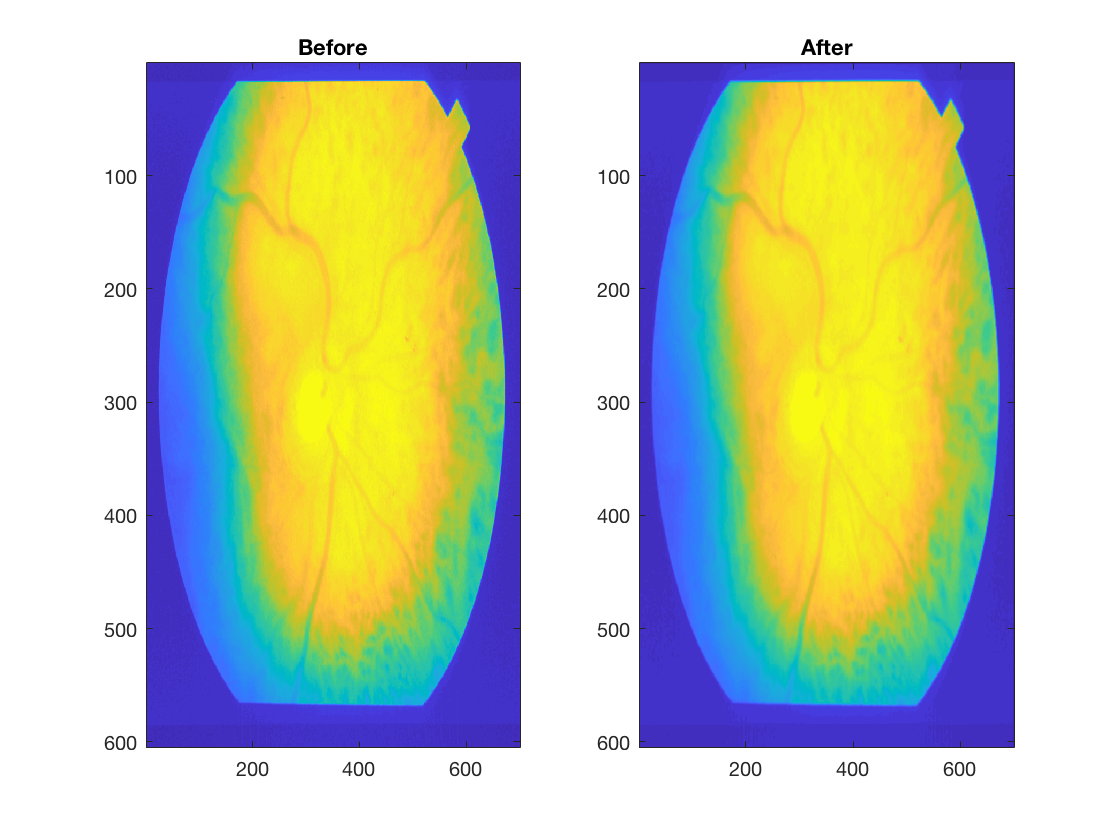


figure
subplot(1,2,1)       
imagesc(red)
title('Before')

subplot(1,2,2)      
imagesc(img_new)    
title('After')

Q5. a.

a=[-3:.1:3];
b=[-3:.1:3];

b. Meshgrid returned a 2-D grid which has coordinates based on the coordinates of vectors a and b. All the rows of A are a copy of a and all the columns in B are a copy of b.

[A, B]=meshgrid(a,b);
whos A

  Name       Size            Bytes  Class     Attributes

  A         61x61            29768  double              



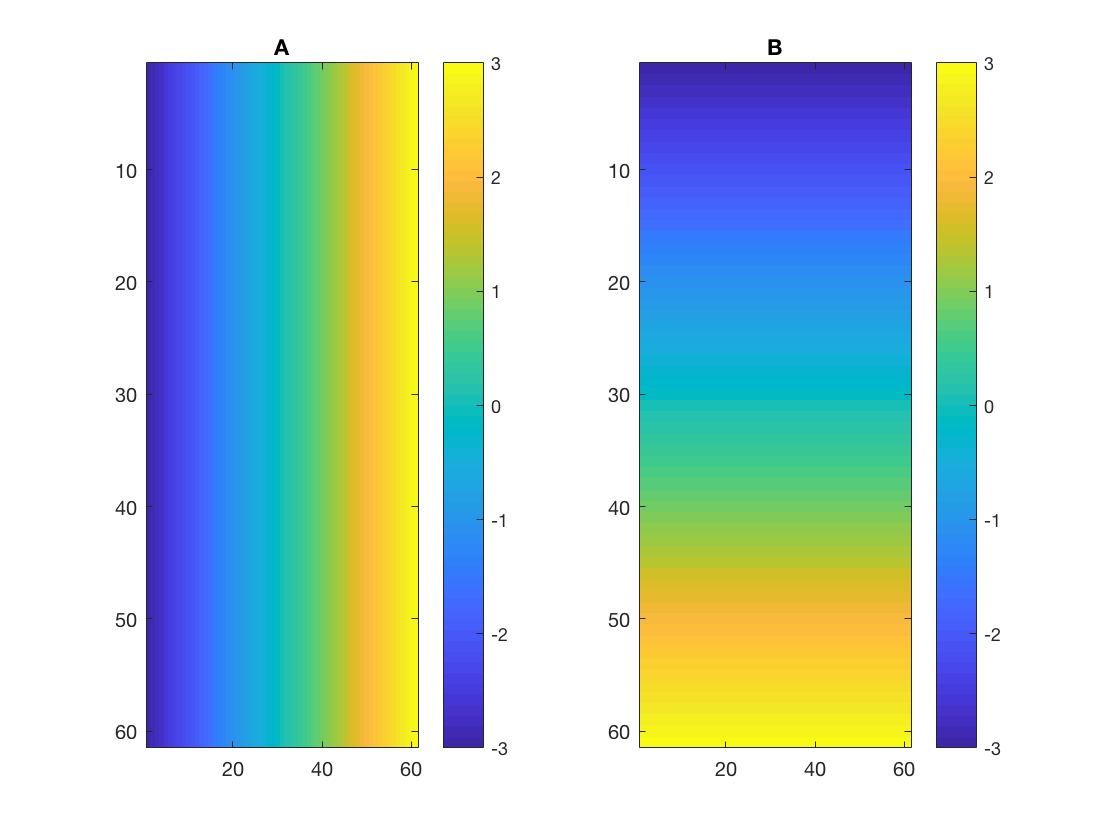


figure
subplot(1,2,1)       
imagesc(A)
colorbar
title('A')

subplot(1,2,2)      
imagesc(B)
colorbar
title('B')

c.

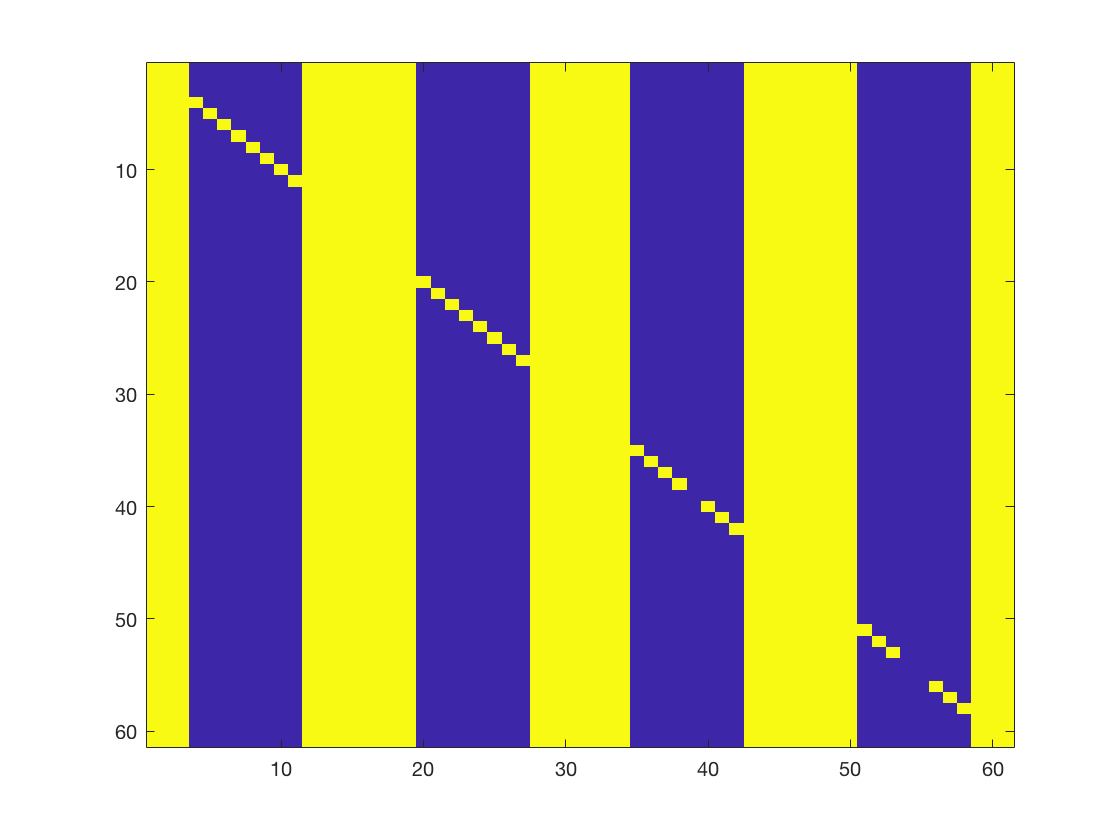

a = (A*A)+(B*B);
b = expm(a*(-1/2));
c = b*cos(4*A);

d = (A+0.5)*(A+0.5);
e = (B*B);
f = -3/2*(d + e);
g = expm(f);
h = c+g;
h(h > 0.001) = 0.001;
h(h < -0.001) = -0.001;
figure
imagesc(h)

d.